global L alpha
n = 9;
m = 14;
d = 3;
size = 1;
alpha = 0.75;
rng(3);

s = [1 1 2 2 3 3 4 4 5 5 6 7 7 8];
t = [2 3 3 4 4 5 5 6 7 9 7 8 9 9];
G = graph(s,t);
H = incidence(G)'*eye(9);
A12 = [1 sqrt(3)/2 0; sqrt(3)/2 1 0; 0 0 0];
A13 = [0  0 0; 0 1 0; 0 0 1];
A23 = [2  1 0; 1 1 0; 0 0 1];
A24 = A13; A34 = A13;
A35 = [1 0 0; 0 0 0; 0 0 0];
A45 = diag([1, 2, 3]);
A78 = eye(3);
A79 = eye(3);
A89 = ones(3,3);
A46 = A89;
A67 = A12;
A57 = A35;
A59 = A13;
W = blkdiag(A12,A13,A23,A24,A34,A35,A45,A46,A57,A59,A67,A78,A79,A89);

Hbar = kron(H,eye(d));
L = Hbar'*W*Hbar;
v=eig(L);
lambda_min = min(v(v>0.0001))

lambda_min = 0.1063

K = 5;
%pi/((d*n)^(0.25*(1-alpha))*(1-alpha)/lambda_min)

x0 = 1800*(rand(d*n,1)-0.5);
V0 = x0'*L*x0/2

V0 = 8.4818e+06

T1 = 2*(2*lambda_min)^(-0.5*(alpha+1))*(x0'*L*x0/2)^(0.5*(-alpha+1))/K/(1-alpha)

T1 = 45.5498

T2 = pi/((d*n)^(0.25*(1-alpha))*(1-alpha)*lambda_min*K)

T2 = 19.2379


%avg = 1/n*kron(ones(1,n),eye(d))*x0;
options = odeset('RelTol',1e-9,'AbsTol',1e-10);

% Consensus
[t1,x1] = ode45(@consensus,[0:0.0001:18],x0,options);
e1 = zeros(length(t1),1); x1 = x1';
for i=1:length(t1)
    e1(i,1) = norm(L*x1(:,i));
end
r1 = find(e1<10e-6,1,'first')


r1 =

  0×1 empty double column vector



t1(r1)


ans =

  0×1 empty double column vector



% Finite-time Consensus
[t2,x2] = ode45(@ft_consensus,[0:0.0001:18],x0,options);
e2 = zeros(length(t2),1); x2 = x2';
for i=1:length(t2)
    e2(i,1) = norm(L*x2(:,i));
end
r2 = find(e2<10e-6,1,'first')

r2 = 171873

t2(r2)

ans = 17.1872

% Fixed-time Consensus
[t3,x3] = ode45(@fxt_consensus,[0:0.0001:18],x0,options);
e3 = zeros(length(t3),1); x3 = x3';
for i=1:length(t3)
    e3(i,1) = norm(L*x3(:,i));
end
r3 = find(e3<10e-6,1,'first')

r3 = 80996

t3(r3)

ans = 8.0995

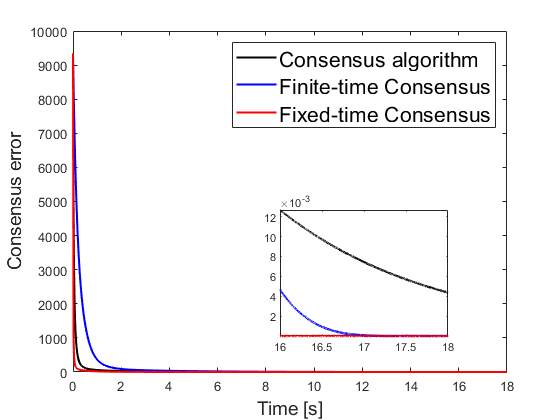

figure
hold on
plot(t1,e1,"-k","LineWidth",1.5);
plot(t2,e2,"-b","LineWidth",1.5);
plot(t3,e3,"-r","LineWidth",1.5);
box on
xlabel('Time [s]',"FontSize",14);
ylabel('Consensus error',"FontSize",14);
legend({'Consensus algorithm','Finite-time Consensus','Fixed-time Consensus'},"FontSize",16,"NumColumns",1)

ax = axes('position',[0.5 .2 .3 .3]);
box on % put box around new pair of axes
hold on
indexOfInterest = (t1 <= 18) & (t1 >= 16); % range of t near perturbation
plot(t1(indexOfInterest),e1(indexOfInterest),"-k","LineWidth",2); % plot on new axes
plot(t2(indexOfInterest),e2(indexOfInterest),"-b","LineWidth",2); % plot on new axes
plot(t3(indexOfInterest),e3(indexOfInterest),"-r","LineWidth",2); % plot on new axes
axis tight
box on;

function dx = consensus(t,x)
    global L
    dx = -5*L*x;
end

function dx = ft_consensus(t,x)
    global L alpha
    dx = -5*sig(L*x,alpha);
end

function dx = fxt_consensus(t,x)
    global L alpha
    dx = -sig(L*x,alpha)-sig(L*x,2-alpha);
    dx = 5*dx;
end

function y = sig(x,alpha)
    y = zeros(length(x),1);
    for i=1:length(x)
        y(i,1) = abs(x(i,1))^alpha*sign(x(i,1));
    end
end